### Del 2: Minstakvadratmetoden för produktionsfunktionen

% Datapunkter
x = [0, 0.5, 1, 1.5, 2, 2.99, 3]';
y = [0, 0.52, 1.09, 1.75, 2.45, 3.5, 4]';

% Ansätter matris
A_mk = [x, x.^2];

% Löser ut koefficienter med MK-metoden
b_mk = A_mk \ y;

% Polynominterpolation av datapunkter (gradtal 6 ger interpolation)
interp = polyfit(x, y, 6);

% x-värden att plotta för
x_range = [0:0.01:3]';

% Uträknade värden av f för MK-metoden
B_mk = [x_range, x_range.^2];
y_mk_pred = B_mk*b_mk;

y_mk_for_points = A_mk*b_mk;

error = norm(y - y_mk_for_points); % ~0.35

error = 0.3531

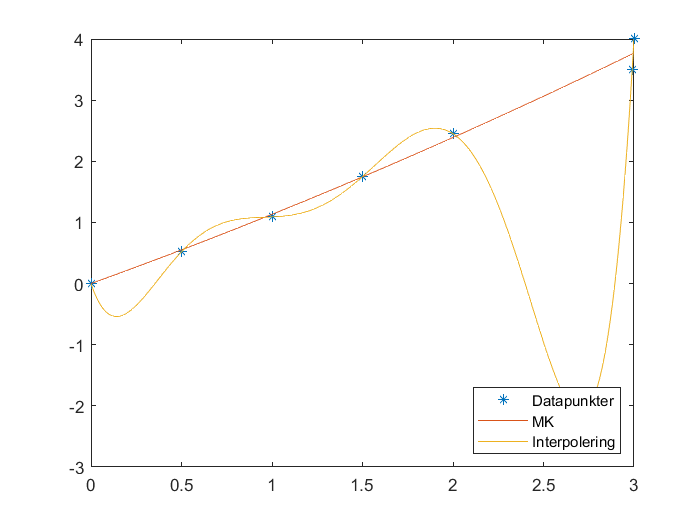


% Uträknade värden av f för interpolation
y_interp_pred = polyval(interp, x_range);

% Plots
plot(x, y, "*");
hold on
plot(x_range, y_mk_pred);
plot(x_range, y_interp_pred);
legend("Datapunkter", "MK", "Interpolering", 'location', 'southeast');
hold off

Felet är ca 0.35 för MK-metoden. Det säger egentligen inte så mycket, men vi ser från grafen att den anpassar bättre till punkterna än polynomet.

Det interpolerande polynomet oscillerar mycket, och får ett stort fel i jämförelse med MK-lösningen på formen aX + bX^2. Det sistnämnda är därmed att föredra.

### Del 3: MK-metoden på nyttofunktionen

#### MK-metoden på (5) via linjärisering

% Datapunkter
x = [150, 200, 300, 500, 1000, 2000]';
y = [2, 3, 4, 5, 6, 7]';

% VL i linjäriseringen av (5) som blir ln(1/U - 1/8) + ln(alfa) =
% ln(a). Det är detta vi vill lösa med MK-metoden.
y_linj_5 = log((y.^-1 - 1/8)) + log(x);

% Ansätter matris
A_linj_5 = [ones(length(x), 1)];

% Löser för att få ln(a)
ln_a_5 = A_linj_5 \ y_linj_5;

% Beräknar a
a_5 = exp(ln_a_5);

% alfa-värden att plotta
x_range = [150:50:2000]';

% Beräknar U(alfa)
y_5_pred = (1/8 + a_5*x_range.^-1).^-1;

% Plots
plot(x, y, "*");
hold on
plot(x_range, y_5_pred);

#### MK-metoden på (6) via linjärisering

% VL i linjäriseringen av (6) som blir ln(8-U) = ln(a) + b*ln(alfa)
y_linj = log((8-y));

% Ansätter matris
A_linj = [ones(length(x), 1), log(x)];

% Löser ut ln(a) och b med MK-metoden
ab = A_linj \ y_linj;

% Bestämmer a och b
a_linj = exp(ab(1));
b_linj = ab(2);

% Beräknar U(alfa)
y_pred = 8 - a_linj*x_range.^b_linj;

% Plot
plot(x_range, y_pred);

#### MK-metoden på (6) via Gauss-Newton

% Initiella gissningar för a och b
a = 100;
b = -0.3;
x_vec = [a; b];

for k=1:10
    % Beräknar residual
    r = y - (8 - a*x.^b);
    
    % Beräknar jakobian
    J = [x.^b, a*log(x).*x.^b];
    
    % Löser ut v
    v = J\(-r);
    
    % Uppdaterar a- och b-värdena
    x_vec = x_vec + v;
    a = x_vec(1);
    b = x_vec(2);
end

% Beräknar U(alfa)
y_gn = 8 - a*x_range.^b;

% Plot
plot(x_range, y_gn);

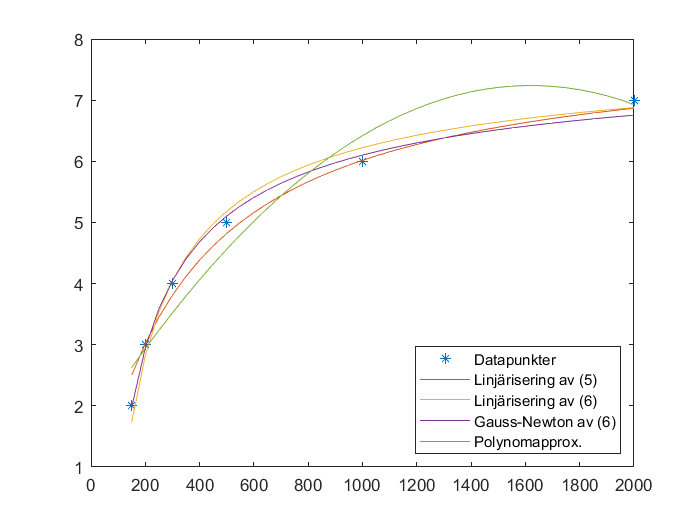

% Polynomanpassning
p = polyfit(x, y, 2);

% Beräknar U(alfa)
y_p = polyval(p, x_range);

% Plots
plot(x_range, y_p);
legend("Datapunkter", "Linjärisering av (5)", "Linjärisering av (6)", "Gauss-Newton av (6)", "Polynomapprox.", 'location', 'southeast');
hold off

I detta fall är linjärisering bäst, eftersom den kräver betydligt färre beräkningar än Gauss-Newton. För linjäriseringen behövs bara ett system lösas en gång, men för Gauss-Newton måste ett system lösas i varje iteration. Om däremot funktionen inte kan linjäriseras, behövs Gauss-Newton.

Polynomapproximation leder till en modell som alltid divergerar då alfa går mot oändligheten. Det är därmed en dålig approximation av de funktioner som ska approximeras.

### Del 4: Sparande med ändlig horisont

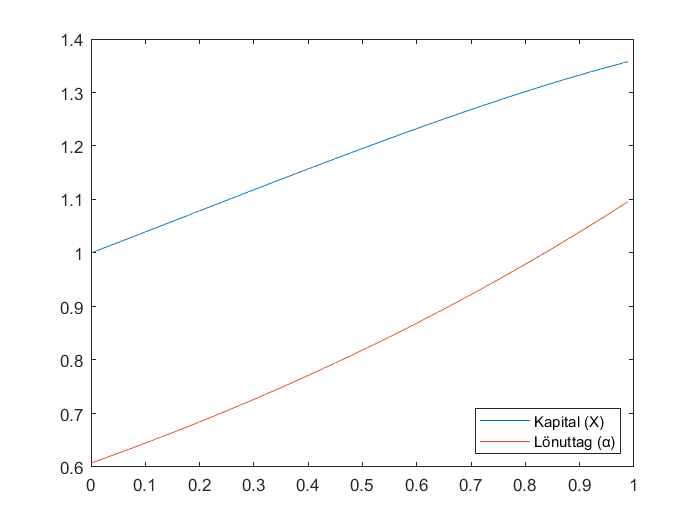

% Initialdata
N = 100;
T = 1;
delta_t = T/N;

% Initialisering
X = ones(N + 1,1);
new_X = ones(N + 1,1);
lambdas = zeros(N,1);

% De olika varianterna på f
f1 = @(x) x;
f1_deriv = @(x) 1;

f2 = @(x) x + (x^2)/10;
f2_deriv = @(x) 1 + x/5;

f3 = @(x) b_mk(1)*x + b_mk(2)*x^2;
f3_deriv = @(x) 1 + 5*x;

% Väljer vilken f som ska användas
f = @(x) f1(x);
f_deriv = @(x) f1_deriv(x);

% Övriga funktioner
g_deriv = @(x) 1/sqrt(x);
alfa = @(n) lambdas(n+1)^(-3/5);

% (10) itereras
for i=1:10
    lambdas(N) = g_deriv(X(N+1));
    
    for n=N-1:-1:1
        lambdas(n) = lambdas(n+1) + delta_t*f_deriv(X(n))*lambdas(n+1);
    end
    
    new_X = X;
    
    for n=1:N
        new_X(n+1) = new_X(n) + delta_t*(f(new_X(n)) - 1/(lambdas(n)^(3/5)));
    end
    
    if (norm(new_X - X) < 0.0001)
        break;
    end
    
    X = new_X;
end

% Tidsintervallet att plotta (ändpunkt exkluderad)
timespan = [0:delta_t:T-delta_t];

% Beräknar alfa-värden från lambda-värden
alfas = lambdas.^(-3/5);

% Plots
plot(timespan, X(1:N));
hold on
plot(timespan, alfas);
legend("Kapital (X)", "Lönuttag (α)", 'location', 'southeast');
hold off

TODO: Studera konvergens/divergens och formulera stoppvillkor

### Del 5: Felkällor

Skattningarna av de funktioner som ingår i lösningen är endast approximationer utifrån de givna datapunkterna. Dessa approximationer kommer ha fel som speglas i den totala lösningen. Utöver detta kommer det största felet vara lösningsmodellen d.v.s Eulers metod. Detta kommer alltid att ge ett fel i lösningen, eftersom det är en diskret approximation av ett kontinerligt förlopp.